# Angiogensis Stochastic Modeling

In this document we are going to present the model of angiogensis based on fractional stochastic differential equations.

For this document we are going to document step by step the definitions of the different parameters that construct this model.

## Parameter Definition

For this model we star by defining the state of the random algorithm in order to be repeateble

% by defining this function we are 
% setting a initial seed for the semi-random
% algorithm, this is going to help us 
% to repeat the script and have the same
% results
randn('state',100)

After running this function we start by defining the paremeters that are going to make this model.

First we define the parameters that are going to define the Brownian Path

T = 1 % time from 0 to 1

T = 1

N = 500 % there are going to be 500 steps

N = 500

dt = T/N % the discrete steps of the brownian

dt = 0.0020

         % path

Now we are going to define the parameters for the Stochastic Differential Equation that is going to define the model.

This model is based in the equation that Stokes & Lauffenburger (1991) developed. This SDE is


$$d\vec{v_i \left(t\right)} =-\beta \;\vec{\;v_i \left(t\right)} \textrm{dt}+\sqrt{\;\alpha }\;\vec{\;{\textrm{dW}}_i \left(t\right)} +\kappa \vec{\;\bigtriangledown a} \;\sin \;\left|\frac{\;\phi_i }{2}\right|\;\textrm{dt}$$


$\beta \;$: decay rate constant of the current velocity

$\alpha :\;$represents the magnitude of random fluctuations and their effect on cell movement

$\kappa :$ the chemotactic responsiveness

$\vec{\bigtriangledown a} :$ attractant concentration gradient

$\phi :$ angle between the direction the tip is moving and that towards the attractant source

$\vec{\;v_i } :$ velocity of the tip of the sprout

$\vec{\;W_i } :$ Brownian path of mean 0 and variance $\alpha \;$

% based on the empirical data extracted
% from stokes and lauffenburger
beta = 1/3 % h^-1

beta = 0.3333

alpha = 40 * 1/3 %µm^2 h-3

alpha = 13.3333

% we define this parameter arbitrarialy
kappa = 1/6 

kappa = 0.1667

## Brownian Path

Now we define the brownian path following the next equation


$$\begin{array}{l}
W_j =W_{j-1} +{\textrm{dW}}_j ,j=2,\ldotp \ldotp \ldotp ,N\\
W_1 =0\\
\textrm{dW}=\sqrt{\delta \;t}N\left(0,\alpha \right)
\end{array}$$


% we define the dW following the equation
% we definen 2 rows that contain N
% elements
% each row correspond with a spatial variable
dW = sqrt(dt)*randn(2,N)

dW =     0.0406   -0.0107   -0.0903   -0.0036    0.0352    0.0427   -0.0333   -0.1459    0.0274   -0.0361   -0.0431    0.0040    0.0576    0.0705   -0.0981   -0.0316   -0.0188   -0.1034    0.0220    0.0263   -0.0147    0.0204   -0.0115    0.0592    0.0220    0.0071    0.0153    0.0217    0.0104   -0.0026    0.0138    0.0322   -0.0207    0.0286   -0.0262    0.0166   -0.0155   -0.0202    0.0125   -0.0215    0.0191    0.0524   -0.0611   -0.0249    0.0071    0.0292    0.0358   -0.0243    0.0426   -0.0199
   -0.0993    0.0031   -0.0163   -0.0885    0.0329    0.0863   -0.0402   -0.0013    0.0467    0.0092   -0.0682   -0.0216    0.0629   -0.0497    0.0073    0.0172    0.0315    0.0816   -0.0017    0.0312    0.0421    0.0166   -0.0044    0.0854    0.0130   -0.0517    0.0080   -0.0653    0.0945    0.0892   -0.0070   -0.0150    0.0400    0.0484   -0.0068    0.0613   -0.0776    0.1024    0.0023    0.0442   -0.0381   -0.0563   -0.0004    0.0207    0.0160   -0.0304   -0.0209    0.0363    0.0822   -

% Now we define the brownian path by the 
% comulative sum of dW 
W = cumsum(dW)

W =     0.0406   -0.0107   -0.0903   -0.0036    0.0352    0.0427   -0.0333   -0.1459    0.0274   -0.0361   -0.0431    0.0040    0.0576    0.0705   -0.0981   -0.0316   -0.0188   -0.1034    0.0220    0.0263   -0.0147    0.0204   -0.0115    0.0592    0.0220    0.0071    0.0153    0.0217    0.0104   -0.0026    0.0138    0.0322   -0.0207    0.0286   -0.0262    0.0166   -0.0155   -0.0202    0.0125   -0.0215    0.0191    0.0524   -0.0611   -0.0249    0.0071    0.0292    0.0358   -0.0243    0.0426   -0.0199
   -0.0587   -0.0076   -0.1066   -0.0922    0.0682    0.1290   -0.0735   -0.1472    0.0741   -0.0269   -0.1114   -0.0176    0.1205    0.0208   -0.0908   -0.0144    0.0127   -0.0217    0.0203    0.0576    0.0273    0.0370   -0.0159    0.1445    0.0350   -0.0446    0.0233   -0.0436    0.1050    0.0866    0.0067    0.0173    0.0193    0.0770   -0.0331    0.0779   -0.0931    0.0822    0.0148    0.0227   -0.0189   -0.0039   -0.0614   -0.0042    0.0231   -0.0011    0.0149    0.0120    0.1248   -0

Now we plot the brownian walk for the x variable and the y variable to see if it make sense

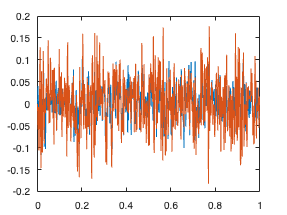

plot([0:dt:T],[0,W(1,:)]), hold on
plot([0:dt:T],[0,W(2,:)]), hold off

## Begining of the modeling

To solve the stochastic differential equation model we define the following L interger and stepsize $\Delta \;t=R\delta \;t$

R = 4;
Dt = R*dt;
L = N/R;

We initialize the solution vector

Xem = zeros(2,L); % first x
                  % second y
Vem = zeros(2,L);

Initialize the first point

Xzero = [0;0];
Xtemp = Xzero;
Vzero = [0;0];
Vtemp = Vzero;

And we initialize the first angles

theta = pi/2;
phi = pi/2;

We define the algorithm to calculate the $\vec{\;\Delta \;a}$

We define the gradient of attractant as


$$a=\frac{\;L}{1+b*\exp \left(-c*y\right)}$$



$$\Delta \;a=\left(0,\frac{\;L*b*c\;*\exp \left(-c*y\right)}{\left(1+b*{\left.\exp \left(-\mathrm{cy}\right)\right)}^2 \right.}\right)$$


addpath("angiogenesis_model/functions/")

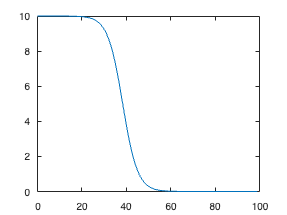

a = [];
L = 10;
b = 10^-5;
c = -0.3;
for i = 1:100
    a(i) = logistic_decay(L,b,c,i-1);
end
plot([0:99],a)

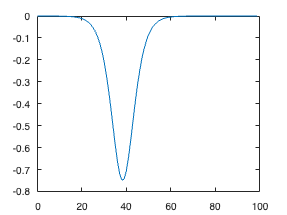

da = [];
L = 10;
b = 10^-5;
c = -0.3;
for i = 1:100
    da(i)= d_logistic_decay(L,b,c,i-1);
end
plot([0:99],da)

We beging the for loop for the model

for j = 1:L

    winc = sum(dW(:,R*(j-1)+1:R*j),2);
    Vtemp = Vtemp ;
end
